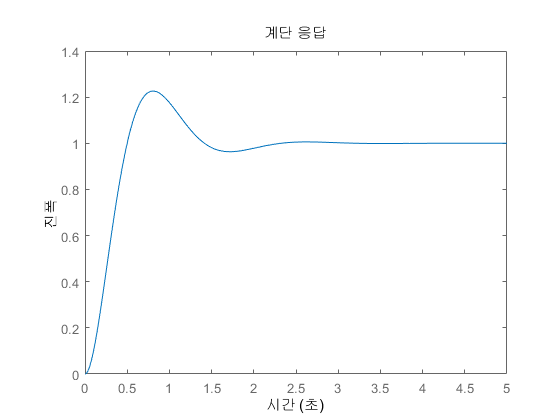

% 6-17
hold off;

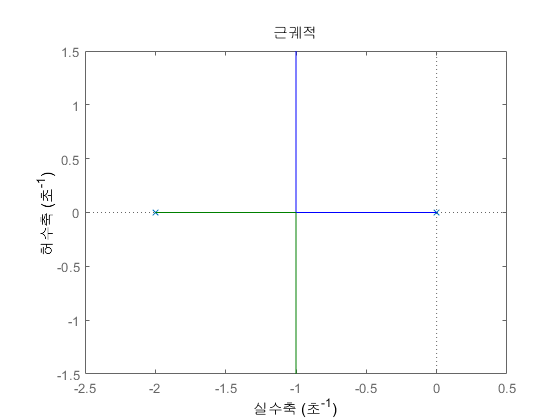

G = @(s) 5/(s*(0.5*s+1));
Gc = @(s) (s+4) / (s+8);
x = -2 + 2*sqrt(3) * 1i;
Kc = abs(real(1/(G(x)*Gc(x))));

s = tf('s');
sysOrig = G(s);
rlocus(sysOrig)

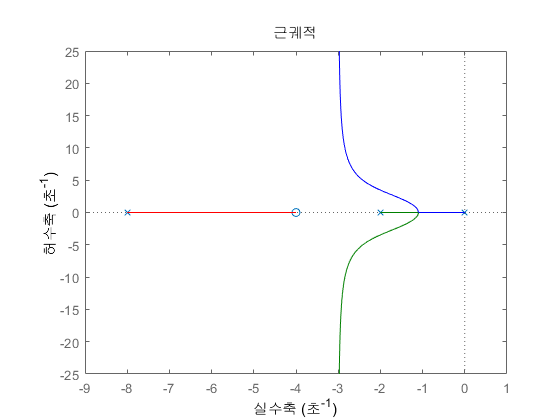

sysLead = Kc * Gc(s) * G(s);
rlocus(sysLead)


t = 0:0.01:5;
% hold;
% step(sysOrig/(sysOrig+1), t);
step(sysLead/(sysLead+1), t);
hold off;